clc
clear
close all
global answer1

##  Identify user purpose

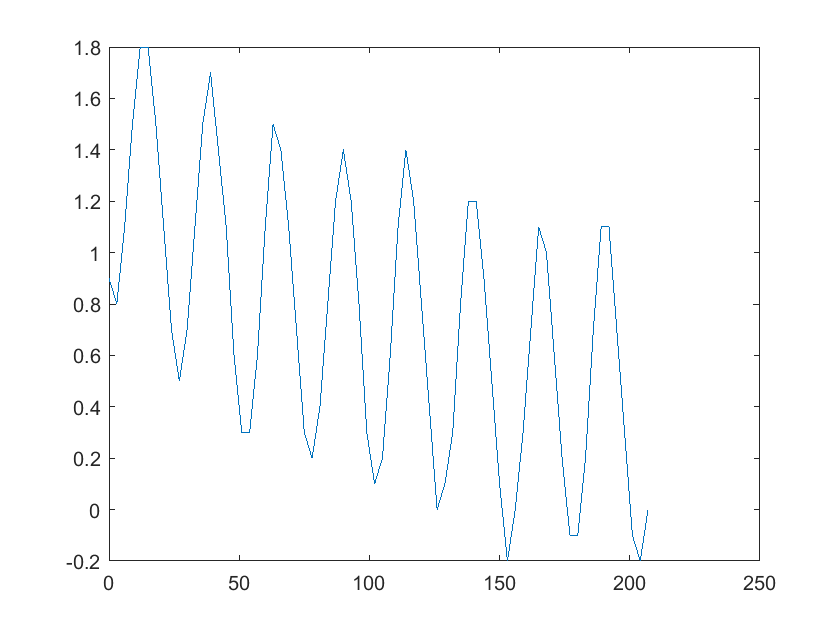

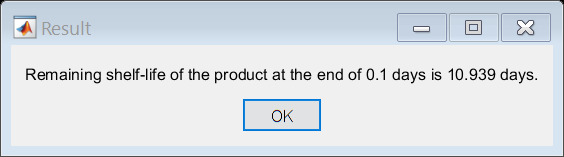

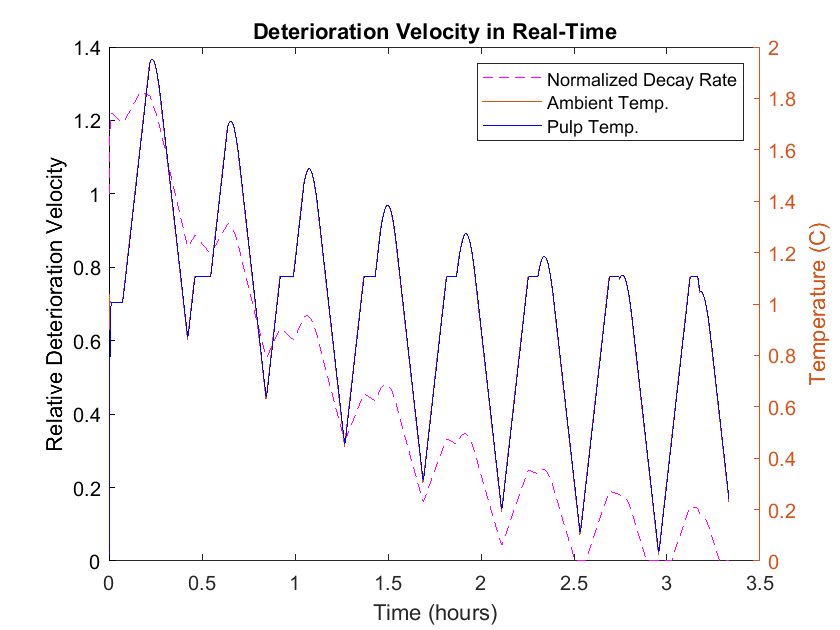

answer1 = questdlg('Select Purpose',	'User Purpose Prompt', ...
	'Pre-trip signal simulation and analysis','Post-trip analysis','Pre-trip signal simulation and analysis');
% Handle response
if strcmp(answer1,"Post-trip analysis")==1
   % Using actual logged temperature and humidity histories, 
   % Estimate the convection coefficient and shelf-life remaining
   
   SLCalculator_v12_Numerical
    
else % The user does not have actual logged temperature and humidity histories
    answer2 = questdlg('Have you identified this plant before?',	'System Identification Prompt', ...
    	'Yes','No','Yes');
    % Handle response
    if strcmp(answer2,"No")==1
       % Identify the system 
       SysIDPrepWS_v18
       
       % Predict ambient temperature profile
        ControlSysSetup_v18
        
        % store simulated temperature and humidity histories
        writematrix([simulatedTemp.Values.Time simulatedTemp.Values.Data],'Input Files/SensorFeed.xlsx','WriteMode','overwritesheet','Sheet','TempRH','Range','A2')
    end
    
        % Using simulated  logged temperature and humidity histories, 
        % Estimate the convection coefficient and shelf-life remaining
        
        SLCalculator_v12_QuicknDirty

    
end